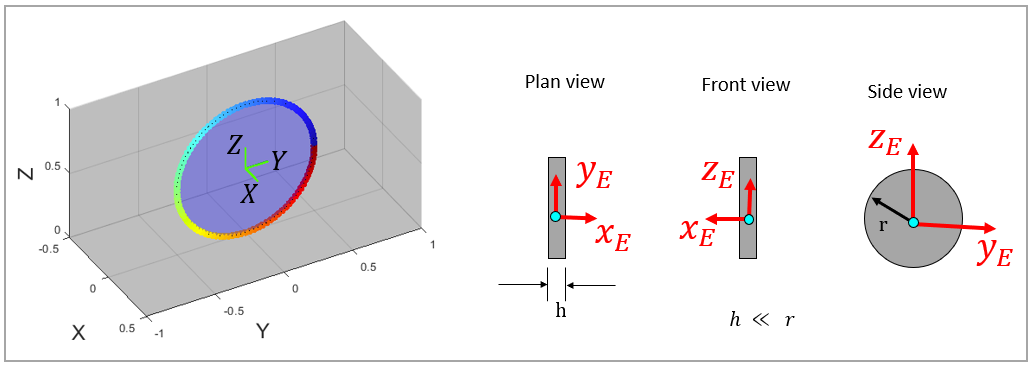

## The Euler angles 

Recall the Euler angle sequence used in the 2 previous derivations.   

- $R_{1Z}$ occurs 1st about the LOCAL **Z** body axis $(\phi)$, aka **YAW**

- $R_{2Y}$ occurs 2nd about the LOCAL **Y** body axis $(\theta)$, aka **PITCH**

- $R_{3X}$ occurs 3rd about the LOCAL **X** body axis $(\psi)$, aka **ROLL**

This Euler angle sequence is illustrated below

     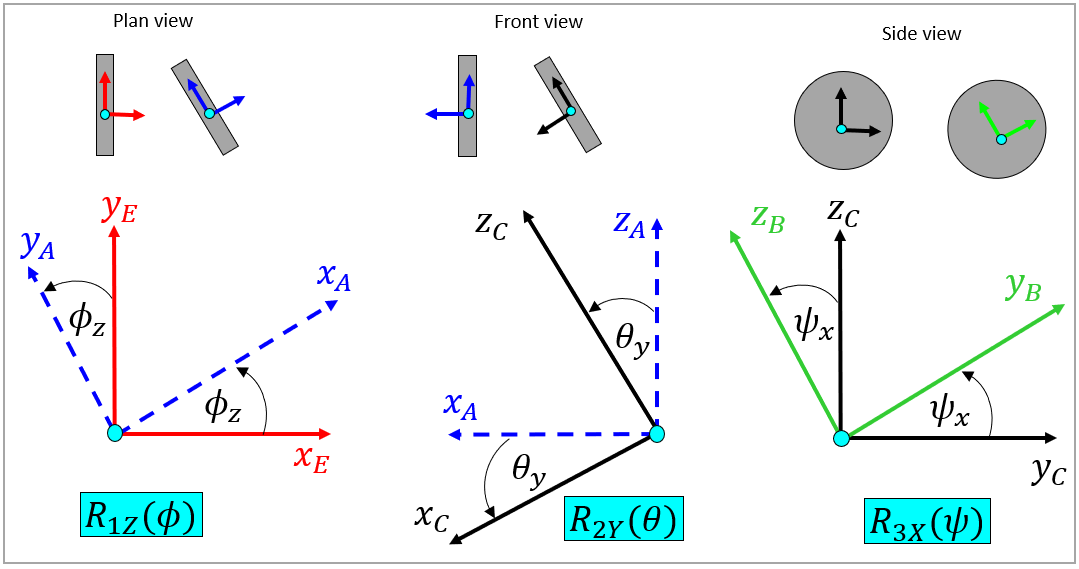   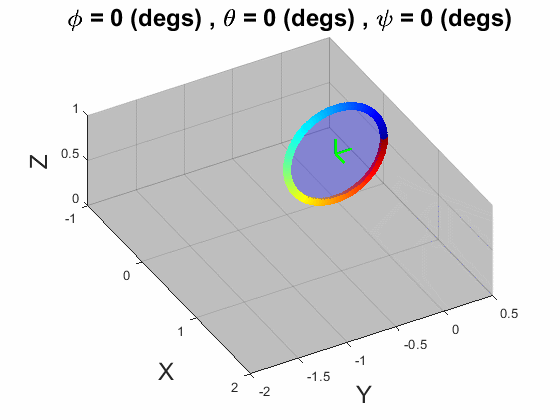

## Define the INITIAL conditions

IC_T.phi       =  deg2rad(45*0);   % (rad)
IC_T.theta     =  deg2rad(10*0);   % (rad)
IC_T.psi       =  deg2rad(0);   % (rad)
IC_T.phi_dot   =  0;             % (rad/sec)
IC_T.theta_dot =  0;             % (rad/sec)
IC_T.psi_dot   =  deg2rad(10); % (rad/sec)

IC_T.rot_ang   = [IC_T.phi, IC_T.theta, IC_T.psi];  % (rad)
IC_T.rot_vel   = [IC_T.phi_dot, IC_T.theta_dot, IC_T.psi_dot];  % (rad/sec)


IC_T

IC_T = struct with fields:
          phi: 0
        theta: 0
          psi: 0
      phi_dot: 0
    theta_dot: 0
      psi_dot: 0.1745
      rot_ang: [0 0 0]
      rot_vel: [0 0 0.1745]


## Open the Simulink model

open_system('bh_test_SPH_joint_ICs')